# Projeto 01 - ES020

## 1. Tensões e Deflexões

### 1.1 Momento Fletor - Função de Singularidade

Algo fundamental para o estudo de Resistência de Materiais é a função de singularidade, que nada mais é do que representar, de forma compacta, uma função por partes, como mostrado abaixo:


$$\langle x - y\rangle^n = \begin{cases} 0 & x < y \\ (x - y)^2 & x \ge y\end{cases}$$


Abaixo demonstra-se duas formas diferentes de se programar tal comportamento, utilizando o momento feltor, para $P = M_0 / L$:

base_numbers = number_gen('215663');           % Generate, from RA, the base numbers
[L, Izz, M0, H] = modeling_data_gen(base_numbers) % Generate, from the Base numbers, the necessary parameters for modeling

L = 63

Izz = 0.3325

M0 = 21000

H = 1.8600

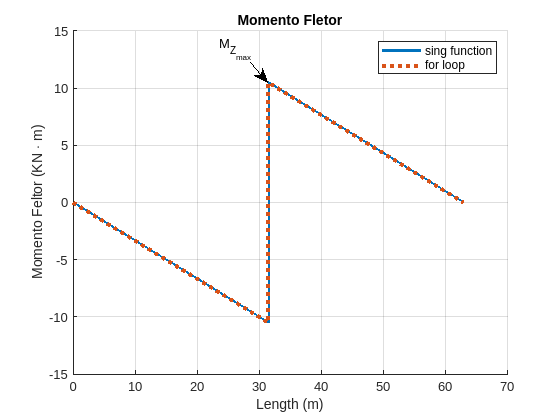


P = M0 ./ L;
X = 0:0.01:L;

% First method, using sing_function
Mz_1 = (P.*L) - M0 - (P.*X) + M0 .* sing_function(X, @(x) x - L./2, 0);

% Second method, using for, if statement
Mz_2 = zeros(size(X)); %Initialize with all zeros

for i = 1:numel(X)
    if (X(i) >= L/2)
        Mz_2(i) = (P.*L) - M0 - (P.*X(i)) + M0;
    else 
        Mz_2(i) = (P.*L) - M0 - (P.*X(i));
    end
end

hold on, grid on;
plot(X, Mz_1 .* 1e-3, LineWidth=2);      % Plot first method, with solid lines
plot(X, Mz_2 .* 1e-3, ":", LineWidth=3); % Plot second method, with dotted lines so we can see both overlapping

title('Momento Fletor');
legend('sing function', 'for loop');
xlabel('Length (m)'), ylabel('Momento Feltor (KN \cdot m)');
annotation(gcf,'textarrow',[0.44765625 0.47734375],[0.851688693098385 0.804698972099853],'String',{'M_{Z_{max}}'});
hold off;

Além de observarmos que ambos os metodos resultam no mesmo gráfico, observamos também que o valor máximo do momento fletor é dado por $M_{z_{max}} = 10.5 KN\cdot m$, no ponto $x =  L/2 = 31.5 m$.

### 1.2 Deflexão

A deflexão da viga é dada por:


$$\nu_y(x) = \frac{1}{EI_{zz}}\left[(PL - M_0)\frac{x^2}{2} - \frac{P}{6}x^3 + \frac{M_0}{2}\left\langle x - \frac{L}{2} \right\rangle^2 \right]$$


Que podemos ver ser dependente do  load $P$ sendo aplicado. A fim de estudar a deflexão como uma função de $x$, mas "parametrizada" por $P$ plotaremos seu valor para diferentes valores do load $P = \left\{ 0, \frac{M_0}{2L}, \frac{M_0}{L}, \frac{2M_0}{L} \right\}$:

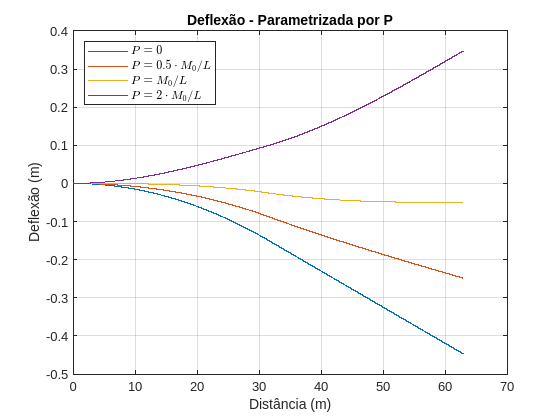

E = 210e6;  % Elasticity coefficient
RHO = 7850; % Density

P = [0; (M0/(2*L)); M0/L; (2*M0/L)]; % All values of the external load to be analyzed
v_y = (1/(E * Izz)) .* ((P .* L - M0) .* (X.^2)./2 - (P .* X.^3)./6 + (M0./2).*sing_function(X, @(x) x - L/2, 2));

plot(X, v_y);
grid on;
title('Deflexão - Parametrizada por P');
xlabel('Distância (m)'), ylabel('Deflexão (m)');
legend('$P = 0$', '$P = 0.5 \cdot M_0/L$', '$P = M_0/L$', '$P = 2\cdot M_0/L$', 'Interpreter', 'latex', Location='northwest');

### 1.3 Tensão

A tensão normal depende tanto do momento fletor no ponto $x$, mas também da altura no ponto da viga sob análise (tendo como ponto de origem da coordenada $y$ o meio da viga), como mostrado abaixo:


$$\sigma_{xx}(x, y)  = - \frac{y}{I_{zz}}M_z(x), \ \ \ -h/2 \le y \le h/2$$


A fim de analisarmos essa função do tipo $z = f(x, y)$, para o load $P = M_0 / L$, iremos analisar a superfície resultante:

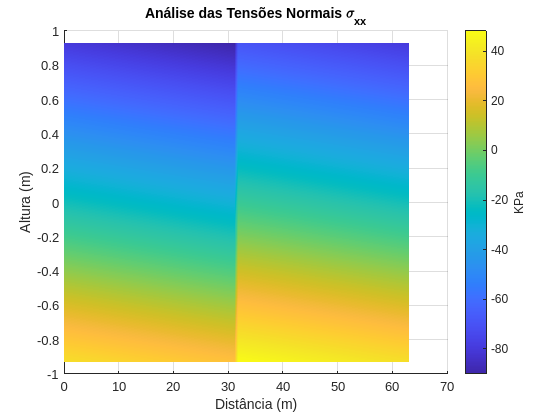

P = M0 / L;
Y = linspace(-H/2, H/2, 100);
X = linspace(0, L, 100);

[X, Y] = meshgrid(X,Y);
sigma = -(Y ./ Izz) .* (P.*L) - M0 - (P.*X) + M0 .* sing_function(X, @(x) x - L./2, 0);

surf(X, Y, sigma * 1e-3);
view(2);

c_bar = colorbar;
shading interp;
title('Análise das Tensões Normais \sigma_{xx}');
xlabel('Distância (m)'), ylabel('Altura (m)');
c_bar.Label.String = 'KPa';